# Ajuste del controlador PI utilizando Reinforcement Learning Motor DC

En este proyecto se muestra cómo sintonizar un controlador PI utilizando el algoritmo de aprendizaje por refuerzo de política determinista profunda de doble retardo (TD3). El rendimiento del controlador ajustado se compara con el de un controlador ajustado con la aplicación Sisotool de MATLAB.

Para tareas de control relativamente sencillas con un pequeño número de parámetros sintonizables, las técnicas de sintonización basadas en modelos como: Sisotool, PID Tuner, etc., pueden obtener buenos resultados con un proceso de sintonización más rápido en comparación con los métodos basados en RL sin modelos. Sin embargo, los métodos RL pueden ser más adecuados para sistemas altamente no lineales o para la sintonización de controladores adaptativos.

Para facilitar la comparación de los controladores, ambos métodos de ajuste utilizan una función objetivo lineal cuadrática gaussiana (LQG).

Este proyecto utiliza un agente de aprendizaje por refuerzo (RL) para calcular las ganancias de un controlador PI.

## Requerimientos mínimos del software

Se recomienda utilizar la versión de MATLAB 9.11 R2021b, los cuales considera los siguientes toolbox:

- Simulink versión 10.4 (R2021b)

- Deep Learning versión 14.3 (R2021b)

- Reinforcement Learning versión 2.1 (R2021b)

Además que, desde MATLAB es posible ajustar el controlador PID en base a técnicas de control por medio de : Sisotool, PID Tuner,  Control System Tuner, etc.

## Modelo del entorno

El modelo de entorno para este proyecto es un modelo de motor DC. El objetivo de este sistema de control es mantener la velocidad del motor para que coincida con un valor de referencia.

open_system('motorDCLQG')

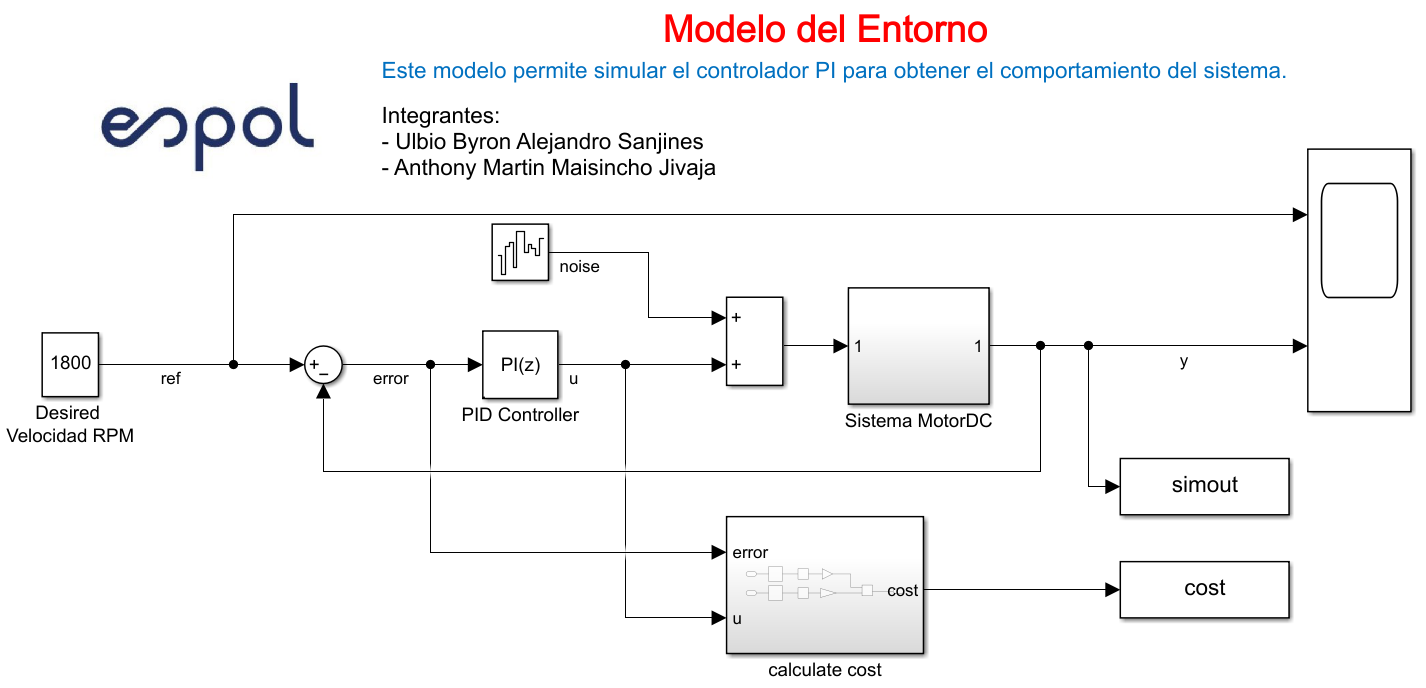

El modelo incluye ruido de proceso con varianza $E\left(n^2 \left(t\right)\right)=1$.

Para mantener la velocidad del motor minimizando el esfuerzo de control u, los controladores de este proyecto utilizan el siguiente criterio LQG.


$$J=\lim_{T\Rightarrow \infty } E\left(\frac{1}{T}\int_0^T \left({\left(\textrm{ref}-v\right)}^2 \left(t\right)+0\ldotp 01u^2 \left(t\right)\right)\textrm{dt}\right)$$


Para simular el controlador en este modelo, se especifica el tiempo de simulación *Tf* y el tiempo de muestreo del controlador *Ts* en segundos.

Ts = 0.1;
Tf = 10;

## Constantes del motor DC

Las constantes del motor DC fueron identificadas previamente, las mismas que servirán de analisis para la sintonisación de las ganancias del controlador PID y este ser comparadas con las resueltas en el algoritmo de Reinforcemente.

J=0.00048115; %Kg.m^2/s^2
B=0.0026829; %N.m
Km=0.22076; %N.m/A
Ka=0.22076; %V.s/rad
R=4.08; %Resistencia
L=0.011307; %Inductancia

Se define la función de transferencia del sistema, la cual es utilizada para ajustar las ganancias del controlador PID

G1=tf([Km],[L*J L*B+R*J R*B+Ka*Km]); %FT de la planta
Q=60/(2*pi); %Factor que transforma de rad/s a RPM
G=G1*Q %FT Velocidad/Voltaje 

G =
 
                 2.108
  -----------------------------------
  5.44e-06 s^2 + 0.001993 s + 0.05968
 
Continuous-time transfer function.



Por medio de comandos de MATLAB, es posible tener la función de transferencia en el tiempo discreto, el mismo que considera el tiempo de muestreo previamente seleccionado.

Gz=c2d(G,Ts) %FT Velocidad/Voltaje Discreta

Gz =
 
       33.86 z + 0.1441
  ---------------------------
  z^2 - 0.03729 z + 1.221e-16
 
Sample time: 0.1 seconds
Discrete-time transfer function.



## Sintonización controlador PI usando Sisotool Toolbox de Matlab

A continuación, se presenta las constantes Proporcional e Integral que fueron resultado de un ajuste manual por medio de *sisotool Toolbox de Matlab.*

En la ventana de comando o el código, es posible indicar lo siguiente.

*sisotool(G)*

Se ejecute y mediante su interfaz se ajusta las ganancias del controlador, tal como se visualiza a continuación:

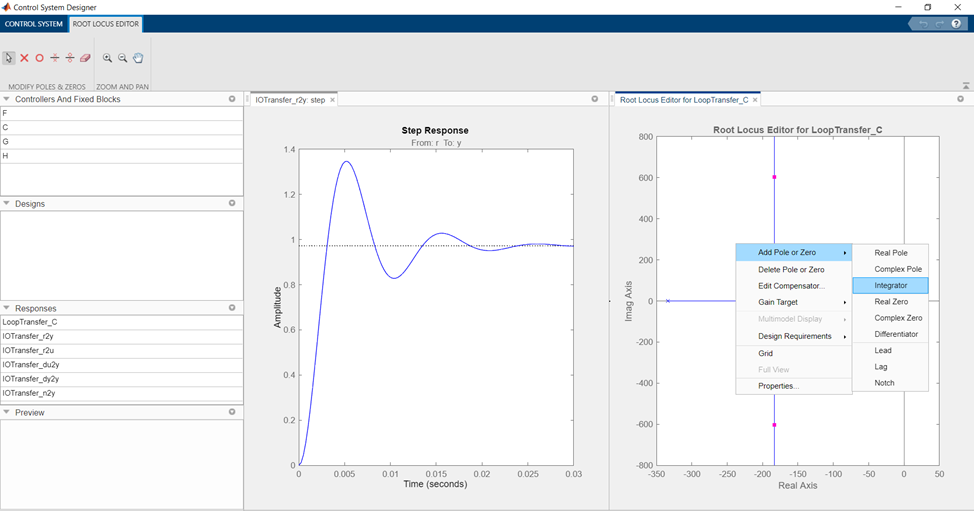

Para ajustar el controlador, se recomienda agregar un integrador para así obtener un error de cero en el estado estacionario. Es posible indicar los diseños de requerimientos en el sistema de control, para ello se debe dirigir en el editor de localización de raices en la planta, clic derecho y colocar dichas etiquetas donde resaltan: tiempo en estado estable, sobrenivel porcentual, frecuencia natrual, radio de amortiguación y limitación de la región.

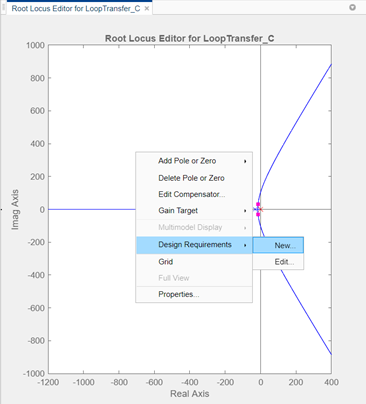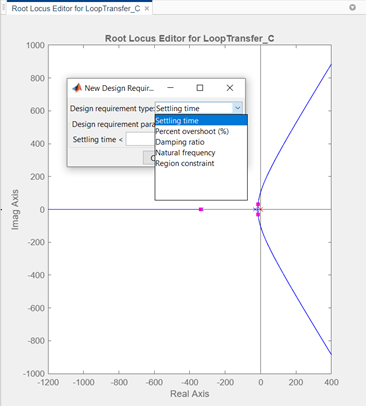

Una vez indicado algún requerimiento del diseño, se van agregando ceros o polos según corresponda al controlador, el cual se identifica con la variable C.

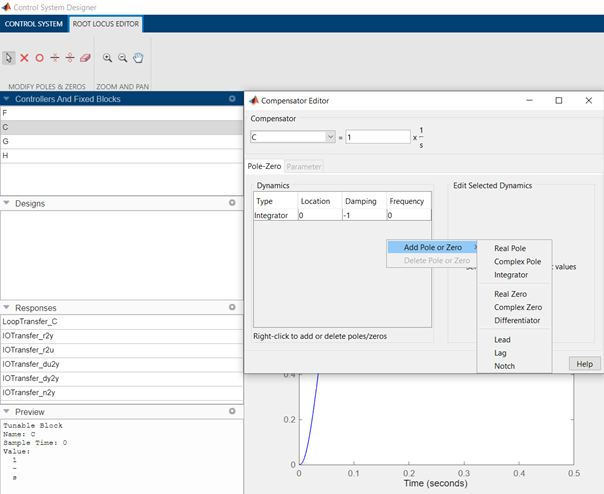

Para observar como esto se encuentra afectando al sistema en la respuesta escalón unitario en lazo cerrado, se activarón las características dando clic derecho y seleccionado todas las variables de interés.

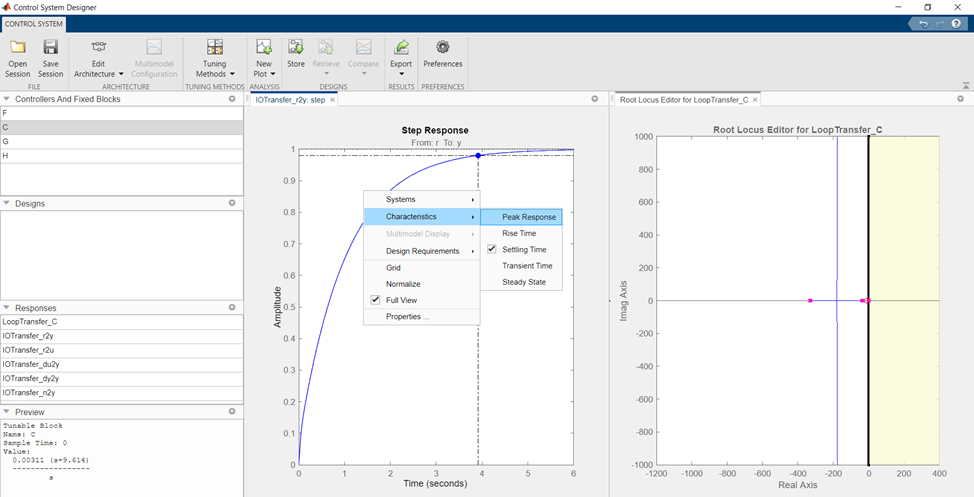

Una vez definida la respuesta deseada, se procede a exportar el controlador, navegando en la pestaña superior denominada export:

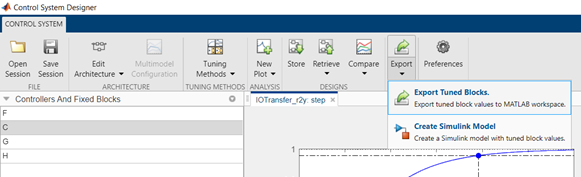

Finalmente se define un nombre y se ubica en el espacio de trabajo de MATLAB.

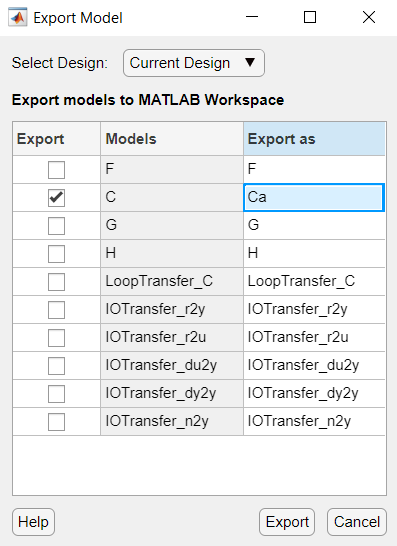

Este modelo de Sisotool es posible acceder en el archivo denominado SISOcontrol.mat, para que el usuario pueda verificar y mejorar las ganancias en el controlador. Con el siguiente comando *load('SISOcontrol.mat'), *es posible cargar dichas configuraciones.

En el código, se escribe la función de transferencia del controlador encontrada para obtener así las ganancias del mismo.

Controlador=zpk(-9.614,0,0.00311)

Controlador =
 
  0.00311 (s+9.614)
  -----------------
          s
 
Continuous-time zero/pole/gain model.



Las constantes del controlador se las obtiene en base al siguiente comando

pid(Controlador)

ans =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.00311, Ki = 0.0299
 
Continuous-time PI controller in parallel form.



El ajuste de las constantes proporcionales e integral resultaron 3.11e-3 y 2.99e-2, respectivamente.

Kp_CST = 0.00311

Kp_CST = 0.0031

Ki_CST = 0.0299

Ki_CST = 0.0299

## Creación del entorno para entrenamiento del Agente

Para definir el modelo entrenamiento del agente RL, se modifica el modelo del motor DC con los siguientes pasos.

- Eliminar el PID Controller.

- Insertar un bloque de RL Agent.

- Crear el vector de observación ${\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & 
\end{array}\right\rbrack }^{T\;}$ donde $e=r-v$,  $v$ es la velocidad del motor DC, y $r$ es la referencia de velocidad. Conectar la señal del observador en el bloque de RL Agent.

- Definir la función de recomepensa para el agente RL como el negativo de los costos LQG, esto es,$\mathrm{Reward}=-\left({\left(\mathrm{ref}-v\right)}^2 \left(t\right)+0\ldotp 01u^2 \left(t\right)\right)$. El agente RL maximiza esta recompensa, minimizando así el coste LQG.

El resultado del modelo es `rlmotorDCPIDTune.slx`.

mdl = 'rlmotorDCPIDTune';
open_system(mdl)

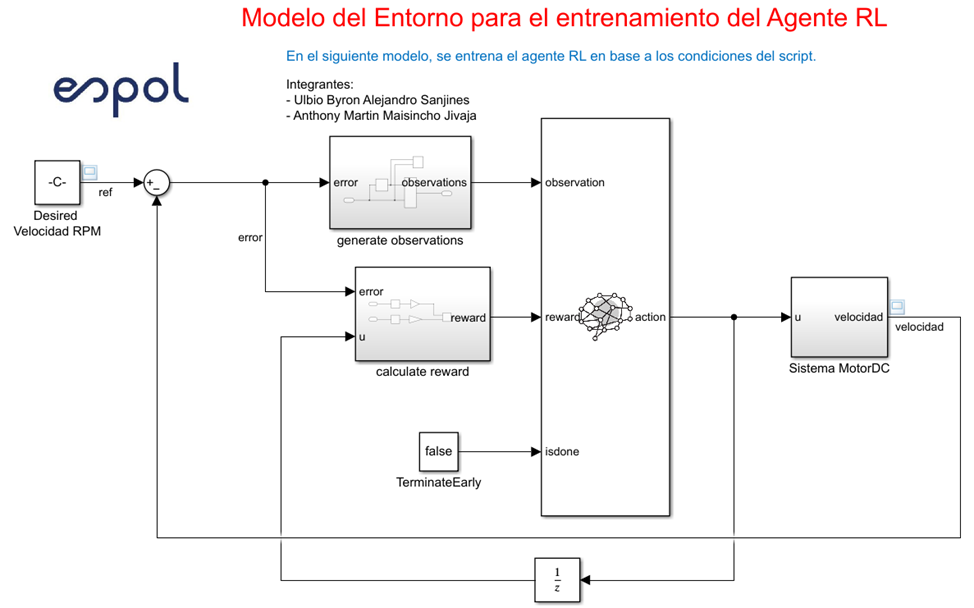

Cree el objeto de interfaz de entorno. Para ello, utilice la función `localCreatePIDEnv` definida al final de este proyecto.

[env,obsInfo,actInfo] = localCreatePIDEnv(mdl);

Se extraen las dimensiones de observación y acción para este entorno.

numObservations = obsInfo.Dimension(1);
numActions = prod(actInfo.Dimension);

Fijar la semilla del generador aleatorio para la reproducibilidad.

rng(0) %Tipo "Twister" Generador de números aleatorios

### **Crear el Agente TD3**

Dadas las observaciones, un agente TD3 decide qué acción realizar utilizando una representación de actor. Para crear el actor, primero hay que crear una red neuronal profunda con la entrada de la observación y la salida de la acción. 

Se puede modelar un controlador PI como una red neuronal con una capa totalmente conectada con observaciones de error e integral de error. 


$$u=\;\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & 
\end{array}\right\rbrack *{\left\lbrack \begin{array}{ccc}
K_i  & K_p  & 
\end{array}\right\rbrack }^{T\;}$$


Donde:

- `u` es la salida de la red neuronal del actor.

- `Kp` y `Ki` son los valores absolutos de los pesos en la red neuronal.

- $e=r-v$,  $v$ es la velocidad del motor DC, y $r$ es la señal de referencia de velocidad deseada.

La optimización del descenso gradual puede llevar los pesos a valores negativos. Para evitar los pesos negativos, sustituya la `fullyConnectedLayer` normal por una `fullyConnectedPILayer`. Esta capa asegura que los pesos sean positivos implementados en la función $Y=\textrm{abs}\left(\textrm{WEIGHTS}\right)*X$.  Esta capa es definida en `fullyConnectedPILayer.m`.

initialGain = single([1e-3 2]);
actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','state')
    fullyConnectedPILayer(initialGain, 'Action')];
actorOptions = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1);
actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,...
    'Observation',{'state'},'Action',{'Action'},actorOptions);

Un agente TD3 aproxima la recompensa a largo plazo dadas las observaciones y las acciones utilizando dos representaciones de función de valor crítico. Para crear los críticos, primero hay que crear una red neuronal profunda con dos entradas, la observación y la acción, y una salida. 

Para crear los críticos, se utiliza la función `localCreateCriticNetwork` definida al final de este proyecto. Utilizar la misma estructura de red para ambas representaciones de críticos.

criticNetwork = localCreateCriticNetwork(numObservations,numActions);

A continuación se presenta la red neuronal del critico

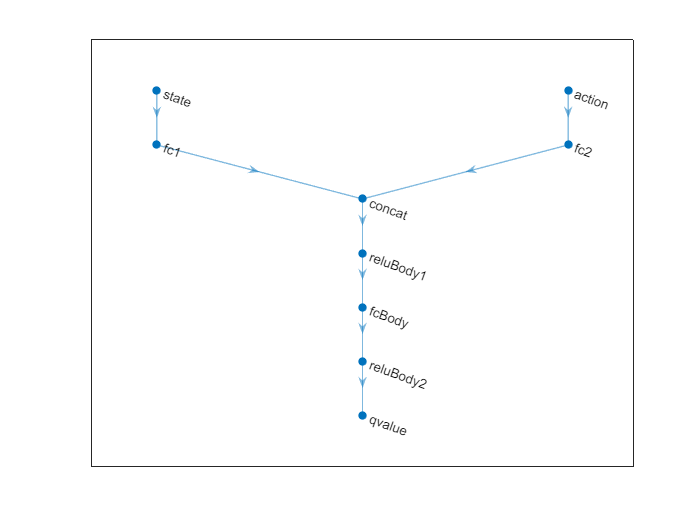

figure
plot(criticNetwork)

Se utilizan dos críticos debido a que cada uno, podrá aprender sobre las ganacias tanto de la constante proporcional e integral individualmente, ya que son valores muy distintos en el ajuste de sus parámetros y deben tener su propio aprendizaje en el sistema.

criticOpts = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1);

critic1 = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,...
    'Observation','state','Action','action',criticOpts);
critic2 = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,...
    'Observation','state','Action','action',criticOpts);
critic = [critic1 critic2];

Configurar el agente con las siguientes opciones:

- Configurar el agente para utilizar el tiempo de muestreo del controlador `Ts`.

- Ajustar el tamaño mini-batch a 128 muestras de experiencia.

- Establecer la longitud del buffer de experiencia en 1e6.

- Establecer el modelo de exploración y el modelo de suavización de la política de objetivos para utilizar ruido gaussiano con varianza de 0,1.

Especificar las opciones del agente TD3 usando [rlTD3AgentOptions](docid:rl_ref#mw_372ffd1e-e1d2-453c-a691-cfef5da40ef8).

agentOpts = rlTD3AgentOptions(...
    'SampleTime',Ts,...
    'MiniBatchSize',128, ...
    'ExperienceBufferLength',1e6);
agentOpts.ExplorationModel.Variance = 0.1;
agentOpts.TargetPolicySmoothModel.Variance = 0.1;

Crear el agente TD3 utilizando la representación del actor, la representación del crítico y las opciones del agente especificadas. 

agent = rlTD3Agent(actor,critic,agentOpts);

## Opciones para el entrenamiento del Agente

Para entrenar el agente, primero se especifican las opciones del entrenamiento:

- Ejecutar cada entrenamiento durante un máximo de 1000 episodios, con una duración de cada episodio de un máximo de 100 pasos de tiempo.

- Mostrar el progreso del entrenamiento en el Gestor de Episodios (establecer la opción `Plots`) y desactivar la visualización de la línea de comandos (establecer la opción `Verbose`).

- Detenga el entrenamiento cuando el agente reciba una recompensa media acumulada superior a -355 en 100 episodios consecutivos. En este punto, el agente puede controlar la velocidad del motor DC.

maxepisodes = 1000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',100, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',-355);

## Entrenamiento del Agente

Se entrena el agente utilizando la función [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852). El entrenamiento de este agente es un proceso computacionalmente intensivo que tarda varios minutos en completarse (incluso horas). Para ahorrar tiempo al ejecutar este proyecto, cargue un agente preentrenado estableciendo `doTraining` en false. Para entrenar el agente usted mismo, establezca `doTraining` a true.

doTraining = false;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('MotorDCPDI2.mat','agent')
end

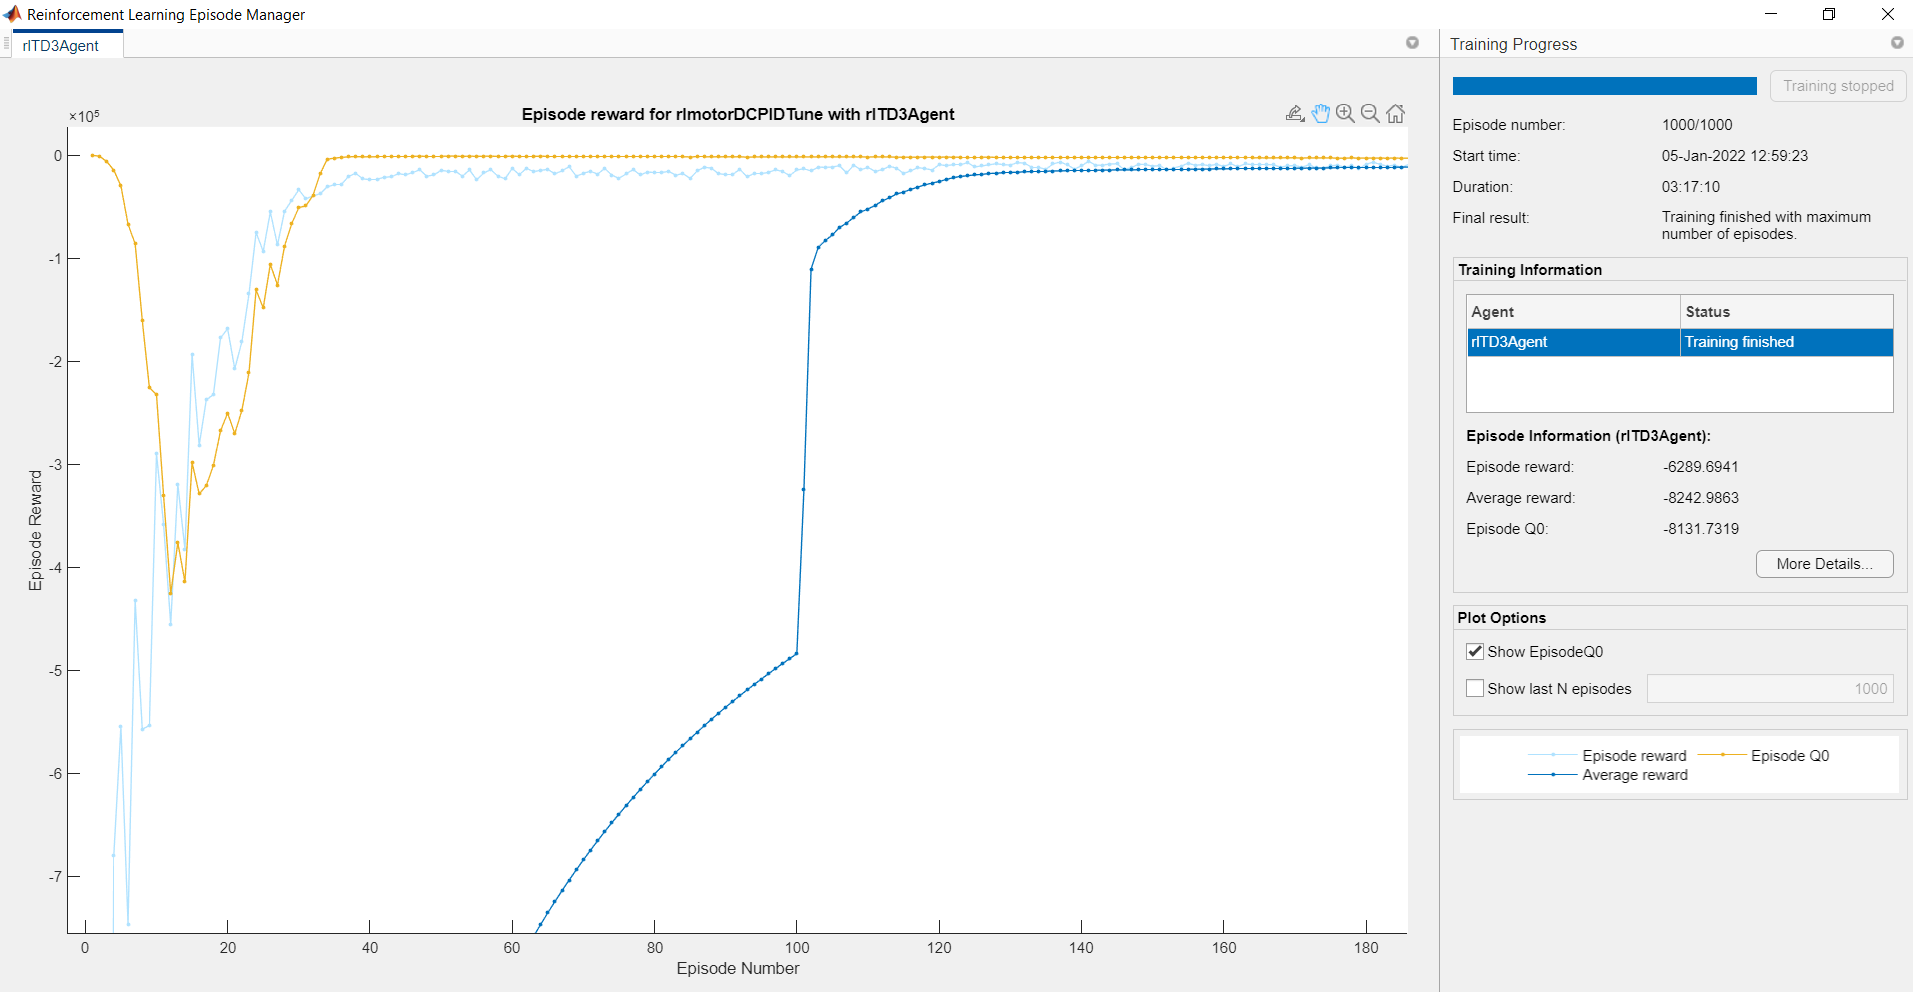

La interfaz del aprendizaje por refuerzo resaltan tres tipo de gráficas que son: Episodio de la recompensa, Promedio de la Recompensa y el Episodio Q0. La curva de color celeste son los episodios de la recompensa, que determina si las acciones tomadas por el entorno son las más eficientes para que sean actuadas en el sistema y así tener la referencia deseada de velocidad, dando pequeñas valoraciones en caso de que llegue a su objetivo, por lo contrario recibirá castigos las cuales le indica al agente RL que sus acciones no son las correctas y debe realizar distintas operaciones. Se evalúa el comportamiento de las recompensas mediante el promedio a través del número de episodios, la cual destaca del color azul. Mientras que la gráfica de los episodios Q0 es el progreso de aprendizaje consecutivo que realiza las acciones del agente, para que el critico aprenda del sistema, este crítico es el que define cuales son las ganancias del controlador para ser ajustados en el Control PID Adaptativo.

%save('MotorDCPDI3.mat','agent');

## Validación del Agente Entrenado

Validar el agente aprendido contra el modelo mediante simulación. Se definen las opciones de simulación y las experiencias del mismo.

simOpts = rlSimulationOptions('MaxSteps',maxsteps);
experiences = sim(env,agent,simOpts);

Las ganancias integral y proporcional del controlador PI son los pesos absolutos de la representación del actor. Para obtener los pesos, primero hay que extraer los parámetros aprendibles del actor.

actor = getActor(agent);
parameters = getLearnableParameters(actor);

Se obtienen las ganancias del controlador.

Ki = abs(parameters{1}(1))

Ki = single
0.0525

Kp = abs(parameters{1}(2))

Kp = single
0.0061

Aplicamos las ganancias obtenidas del agente RL al bloque original del controlador PI y ejecutar una simulación step-response.

mdlTest = 'motorDCLQG';
open_system(mdlTest);
set_param([mdlTest '/PID Controller'],'P',num2str(Kp))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki))
sim(mdlTest)

Extraer la información de la respuesta al escalón, el coste de LQG y el margen de estabilidad para la simulación. Para calcular el margen de estabilidad, se utilizó la función `localStabilityAnalysis` definida al final de este proyecto.

rlStep = simout;
rlCost = cost;
rlStabilityMargin = localStabilityAnalysis(mdlTest);

A continuación, se aplican las ganancias obtenidas con el sintonizador del sistema de control al bloque original del controlador PI y ejecutamos una simulación step-response.

set_param([mdlTest '/PID Controller'],'P',num2str(Kp_CST))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki_CST))
sim(mdlTest)
cstStep = simout;
cstCost = cost;
cstStabilityMargin = localStabilityAnalysis(mdlTest);

## Comparar las respuesta del Controlador

Se grafica el step-response para cada sistema PI.

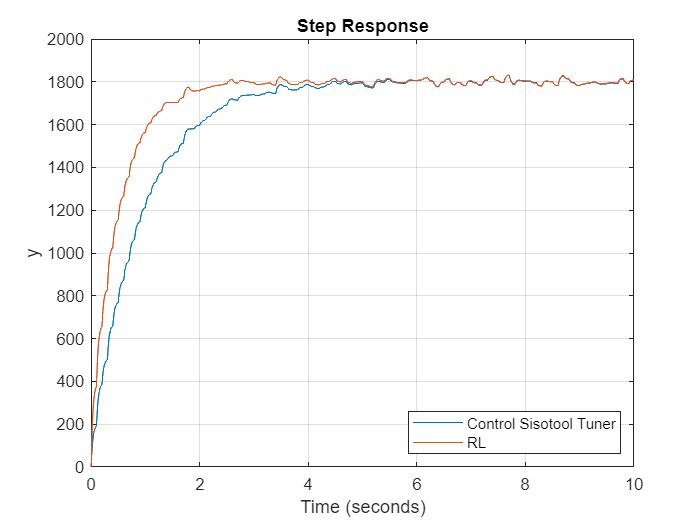

figure
plot(cstStep)
hold on
plot(rlStep)
grid on
legend('Control Sisotool Tuner','RL','Location','southeast')
title('Step Response')

En la gráfica anterior presenta los resultados sobre las constantes ajustadas por el usuario y las obtenidas por medio del algoritmo de RL. El sistema contiene un ruido blanco, por ese motivo es que existen pequeñas variaciones durante su recorrido en la estabilización que es el punto de referencia de 1800 RPM. Gráficamente se observa que el sistema tiene un comportamiento sobre amortiguado y que el algoritmo RL tiene una mejor respuesta que la ajustada por el usuario, debido a que tiene un tiempo de estabilización menor y por tanto la constante de amortiguación es menor. Las respuestas en estado estable son muy similares y cumplen que las dos llegan a su objetivo que es el punto de referencia deseado.

Se analiza la respuesta obtenida por cada simulación.

rlStepInfo = stepinfo(rlStep.Data,rlStep.Time);
cstStepInfo = stepinfo(cstStep.Data,cstStep.Time);
stepInfoTable = struct2table([cstStepInfo rlStepInfo]);
stepInfoTable = removevars(stepInfoTable,{...
    'SettlingMin','SettlingMax','Undershoot','PeakTime'});
stepInfoTable.Properties.RowNames = {'Control Sisotool Tuner','RL'};
stepInfoTable

stepInfoTable = 2×5 table
                              RiseTime    TransientTime    SettlingTime    Overshoot     Peak 
                              ________    _____________    ____________    _________    ______

    Control Sisotool Tuner      2.045        5.2015           5.2015        1.2945      1831.4
    RL                         1.1064          2.17             2.17        1.1825        1831


En la tabla anterior, se especifican cuales son las características del sistema obtenidas con la simulación en lazo cerrado de las constantes PI, las obtenidas por el Sisotool y del algoritmo RL. Como se indicó graficamente, el algoritmo RL presenta un mejor desempeño en la respuesta obtenida ya que le toma menor tiempo en llegar al punto referencia de velocidad, teniendo así un margen de alrededor 3.0315 segundos de diferencia, de igual forma en el tiempo pico el cual existe un margen de 0.9386 segundos. Mientras que las perturbaciones por el ruido blanco incorporado, hace que el sistema presente ciertos picos que conducen a un sobrenivel porcentual, el mismo que es inferior con 1.1825% por parte del algoritmo óptimo. Finalmente, los valores máximos de picos en el sistema resultan ser iguales.

Se comparan los costos acumulados LQG para los dos controladores. El controlador ajustado por RL produce una solución ligeramente más óptima.

rlCumulativeCost  = sum(rlCost.Data)

rlCumulativeCost = -9.4182e+06

cstCumulativeCost = sum(cstCost.Data)

cstCumulativeCost = -1.6170e+07

Ambos controladores producen respuestas estables, mientras que el controlador ajustado por Sisotool produce una respuesta más lenta. Sin embargo, el método de sintonización RL produce un mayor margen de ganancia y una solución más óptima, con el tiempo menor teniendo así una velocidad deseada mucho más rápida. Las ganancias encontradas por el algoritmo RL le toma un inferior esfuerzo en comparación con las ganancias ajustadas en Sisotool, esto podemos notarlo en los valores de costos que resultan más cercanos a cero que con la propuesta por el usuario.

## Funciones locales

Función para crear el entorno RL en el motor DC.

function [env,obsInfo,actInfo] = localCreatePIDEnv(mdl)

% Define las especificaciones del observador como obsInfo y las d la acción como actInfo.
obsInfo = rlNumericSpec([2 1]);
obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error and error';

actInfo = rlNumericSpec([1 1]);
actInfo.Name = 'PID output';

% Build the environment interface object.
env = rlSimulinkEnv(mdl,[mdl '/RL Agent'],obsInfo,actInfo);

% Set a cutom reset function that randomizes the reference values for the model.
env.ResetFcn = @(in)localResetFcn(in,mdl);
end

Función para randomizar la señal de referencia e inicial de la velocidad en el motor DC, los cuales serán ajustados constemente en cada episodio.

function in = localResetFcn(in,mdl)

% Randomiza la señal de referencia
blk = sprintf([mdl '/Desired \nVelocidad RPM']);
vRef = 10 + 4*(rand-0.5);
in = setBlockParameter(in,blk,'Value',num2str(vRef));

% Randomiza la velocidad inicial
vInit = 0;
blk = [mdl '/Sistema MotorDC/V'];
in = setBlockParameter(in,blk,'InitialCondition',num2str(vInit));

end


Función para linealizar y calcular los márgenes de estabilidad del sistema SISO motor DC.

function margin = localStabilityAnalysis(mdl)

io(1) = linio([mdl '/Sum1'],1,'input');
io(2) = linio([mdl '/Sistema MotorDC'],1,'openoutput');
op = operpoint(mdl);
op.Time = 5;
linsys = linearize(mdl,io,op);

margin = allmargin(linsys);
end

Función para crear la red neuronal que actúa como regresor.

function criticNetwork = localCreateCriticNetwork(numObservations,numActions)
statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','state')
    fullyConnectedLayer(300,'Name','fc1')];
actionPath = [
    featureInputLayer(numActions,'Normalization','none','Name','action')
    fullyConnectedLayer(300,'Name','fc2')];
commonPath = [
    concatenationLayer(1,2,'Name','concat')
    reluLayer('Name','reluBody1')
    fullyConnectedLayer(300,'Name','fcBody')
    reluLayer('Name','reluBody2')
    fullyConnectedLayer(1,'Name','qvalue')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);

criticNetwork = connectLayers(criticNetwork,'fc1','concat/in1');
criticNetwork = connectLayers(criticNetwork,'fc2','concat/in2');
end